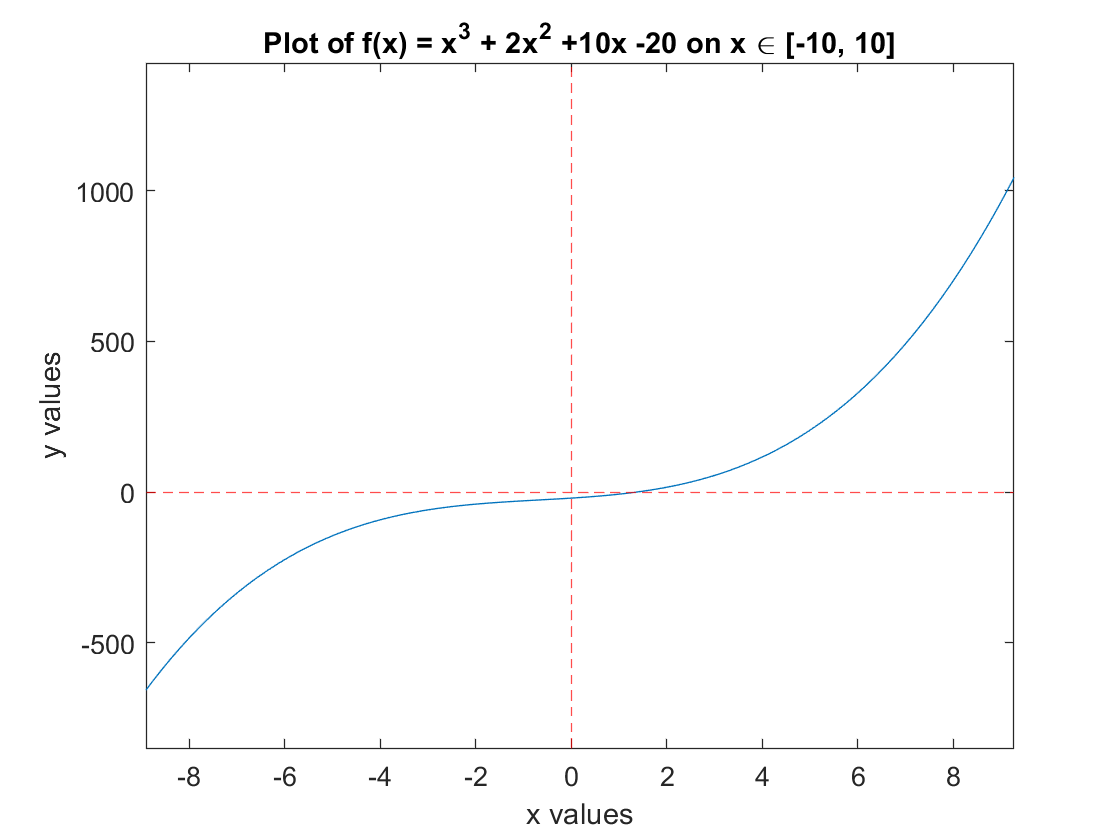

format long
syms x;
f = x*(10 + x*(2 + x*(1))) - 20;
a=10;
xvals = linspace(-a,a);
yvals = vpa(subs(f, x, xvals), 16);


plot(xvals, yvals)
title('Plot of f(x) = x^3 + 2x^2 +10x -20 on x \in [-10, 10]')
yline(0,'r--')
xline(0, 'r--')
xlabel('x values')
ylabel('y values')


x0=1.1;
N=5;
err = 0.00000000001;
m=1; 

[root1, iterations1] = newton(f, x0, N, err, m);

i = 0, xn =   1.100000000000, error = 5.249000000000e+00 
i = 1, xn =   1.391125901276, error = 4.7387190826367426e-01 
i = 2, xn =   1.368951473083, error = 3.0245790409293566e-03 
i = 3, xn =   1.368808113771, error = 1.2550446848420312e-07 
i = 4, xn =   1.368808107821, error = 2.1612220217541788e-16 


function [root,iterations] = newton(f, x0, N, err, m)
    i=0;
    syms x;
    fd = diff(f);
    y = subs(f, x, x0);
    dy = subs(fd, x, x0);
    xn = x0;
    fprintf('i = %d, xn = %16.12f, error = %16.12e \n', i, xn, abs(y))
    while (abs(y) > err) && (i <= N-1)
        root = xn - ((m*y)/dy);
        y = subs(f, x, root);
        i = i + 1;
        fprintf('i = %d, xn = %16.12f, error = %16.16e \n', i, root, abs(y))
        dy = subs(fd, x, root);
        xn = root;
    end
    iterations = i;
end